# 2D-Projectile Simulation

clear;clc;

m = 1;
c = 0.5;
g = 9.81;

projectile_dynamics = @(t,q) [q(3); q(4); -(c/m)*sqrt(q(3)^2+q(4)^2)*q(3); -(c/m)*sqrt(q(3)^2+q(4)^2)*q(4)-g];

## Integrate using ODE45

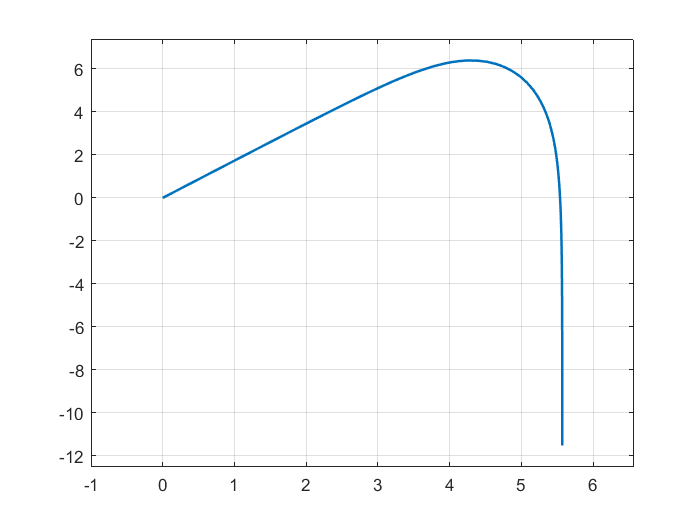

T = 5;
q0 = [0; 0; 100; 100*tan(pi/3)];
[t,q] = ode45(projectile_dynamics,[0 T],q0);

plot(q(:,1),q(:,2),'LineWidth',1.5);
axis([min(q(:,1))-1 max(q(:,1))+1 min(q(:,2))-1 max(q(:,2))+1]);
grid on;

## Animate Projectile

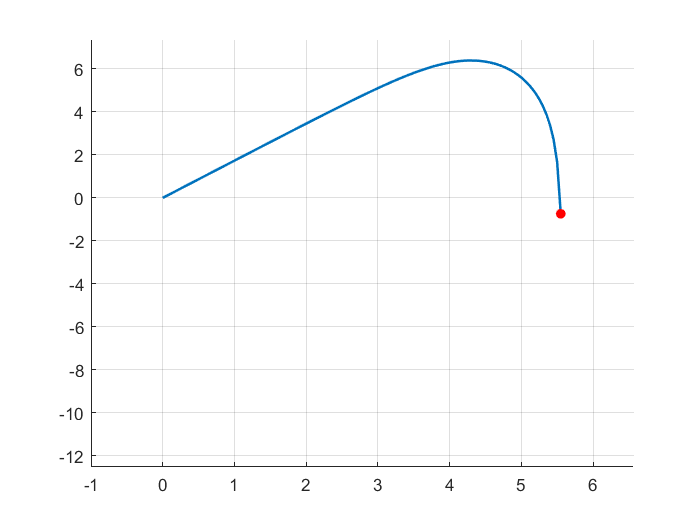

xq = 0:0.05:max(q(:,1));
yq = interp1(q(:,1),q(:,2),xq);

figure(1);
for k=1:length(xq)
    clf;
    hold on;
    plot(xq(1:k),yq(1:k),'LineWidth',1.5);
    plot(xq(k),yq(k),'.','MarkerSize',20,'Color','red');
    axis([min(q(:,1))-1 max(q(:,1))+1 min(q(:,2))-1 max(q(:,2))+1]);
    grid on;
    drawnow;
end